response_data_type = {'voltage', 'normal current density'};

metric = 'nmsq';

IPs_IDs1 = 32820:2:32868;

IDs_current_density = [14390, 7400, 4060, 16000, 19860, 23802, 30002, 23822,21212, 8437];

IDs = {py.list(IPs_IDs1), py.list(IDs_current_density)};

IDs_matarr = {IPs_IDs1, IDs_current_density};

IDs_types = {'Internal Points','Mesh Points'};


source_parameters = {'BARE','BARE'};

parameters= {'CA00','CB00'};

%DOE_range1 = [4.0, 10.0; 3, 8.0]; 
DOE_range1 = [0.005, 0.2; 0.005,  0.15];

%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 1);

DOE_sample_points1 = reverse_normalization(Central_composite_points, DOE_range1);

%DOE_sample_points = [DOE_sample_points ;reverse_normalization(Central_composite_points, DOE_range2)];
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_0';
simulation_seed_folder = fullfile(root_folder, 'Initial_files');

collection_dir = fullfile(root_folder, 'Simulation_results');

parameters_np_array1 = convert_arr_to_python_2d_list(DOE_sample_points1);

%testing_par_value = DOE_sample_points1(1,:);

%test_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(source_parameters), py.list(parameters), testing_par_value, simulation_seed_folder, collection_dir,  py.list(response_data_type), py.list(IDs),  py.list(IDs_types));
%test_data = convert_pydict2data(test_dict,1);
snapshots_py = py.BEASY_IN_OUT2.snapshots_for_given_parameters_and_IDs(py.list(source_parameters), py.list(parameters), parameters_np_array1, py.list(IDs), py.list(response_data_type), simulation_seed_folder, collection_dir, py.list(IDs_types));

snapshots_0 = double(snapshots_py);

%saving_snapshots
csvwrite('Snapshots_year_0.csv', snapshots_0);
csvwrite('DOE_sample_points_year0.csv', DOE_sample_points1 );

snapshots_0

snapshots_0 = 	1.0e+03 *

   -1.0596   -1.0577   -1.0569   -1.0507   -1.0649   -1.0645   -1.0645   -1.0628   -1.0648   -1.0648   -1.0667   -1.0619   -1.0619   -1.0621   -1.0624   -1.0596   -1.0572   -1.0503   -1.0641   -1.0646   -1.0615   -1.0635   -1.0605   -1.0580   -1.0508   -0.1997   -0.2240   -0.1957   -0.3096   -0.2224   -0.3094   -0.3229   -0.2244   -0.2038    0.0002
   -1.0497   -1.0400   -1.0076   -1.0008   -1.0607   -1.0569   -1.0569   -1.0491   -1.0262   -1.0262   -1.0197   -1.0110   -1.0110   -1.0133   -1.0519   -1.0411   -1.0092   -1.0006   -1.0525   -1.0279   -1.0183   -1.0529   -1.0421   -1.0104   -1.0011   -0.4021   -0.5053   -0.2530   -0.4520   -0.2749   -0.8690   -1.0466   -0.4825   -0.4424    0.0002
   -1.0089   -1.0121   -1.0463   -1.0421   -1.0121   -1.0139   -1.0139   -1.0140   -1.0451   -1.0451   -1.0610   -1.0570   -1.0570   -1.0591   -1.0177   -1.0184   -1.0464   -1.0418   -1.0203   -1.0480   -1.0530   -1.0197   -1.0199   -1.0472   -1.0422   -0.3298   -0.2434  

surrogates_0 = response_surface(DOE_sample_points1, snapshots_0,2);
%}

testing_par_value = [0.02, 0.02];

test_output_from_surrogate = output_from_surrogates(testing_par_value, surrogates_0,cellfun('length',IDs_matarr)); 

test_folder = '';
for i = 1:length(parameters)
    test_folder =   strcat(test_folder, parameters{i},'_', num2str(testing_par_value(i), '%.4f'));
    if i~=length(parameters)
        test_folder = strcat(test_folder, '_');
    end
end

test_dir = fullfile(collection_dir, test_folder);
files_name = "BU_TimeStepped_01_0";
if ~isfolder(test_dir)
    test_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(source_parameters), py.list(parameters), testing_par_value, simulation_seed_folder, test_colection_dir,  py.list(response_data_type), py.list(IDs),  py.list(IDs_types));
    test_data = convert_pydict2data(test_dict,1);
else

    test_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(test_dir, files_name, py.list(response_data_type),  py.list(IDs), py.list(IDs_types));
    test_data = convert_pydict2data(test_dict,0);
end

normalised_mean_sq_diff(test_output_from_surrogate, test_data, response_data_type, [0 0, 0, 1])

%
parameters= {'CA00','CB00'};
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_0';
files_name = 'BU_TimeStepped_01_0';

calib_dir = fullfile(root_folder,'Calibration_data');
simulation_seed_folder = fullfile(root_folder, 'Initial_files');
%calib_dir1 = 'C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_nonlinear\Parameter_BARE_BBS\Measurement_results3';

calib_data_IDs = {IPs_IDs1, IDs_current_density};
calib_data_type = response_data_type(1:2);


%calib_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(calib_data_type),  py.list(calib_data_IDs), py.list(IDs_types));

%calib_data = convert_pydict2data(calib_dict,0);

calib_data_file_err_inc = 'data_with_error.xlsx';

if ~isfile(fullfile(calib_dir, calib_data_file_err_inc))
    all_position_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(calib_dir, files_name, py.list(calib_data_type),  py.list(calib_data_IDs), py.list(IDs_types));
    all_position_data = convert_pydict2data(all_position_dict,0);
    introduce_error_and_write_file( {IPs_IDs1.', IDs_current_density.'},all_position_data, calib_dir, calib_data_file_err_inc,1);
end
%model_out = output_from_surrogates([2.0, 3.0], surrogates, [17,6]);

calib_data_inc_error = data_from_tables(fullfile(calib_dir, calib_data_file_err_inc), calib_data_IDs,3);

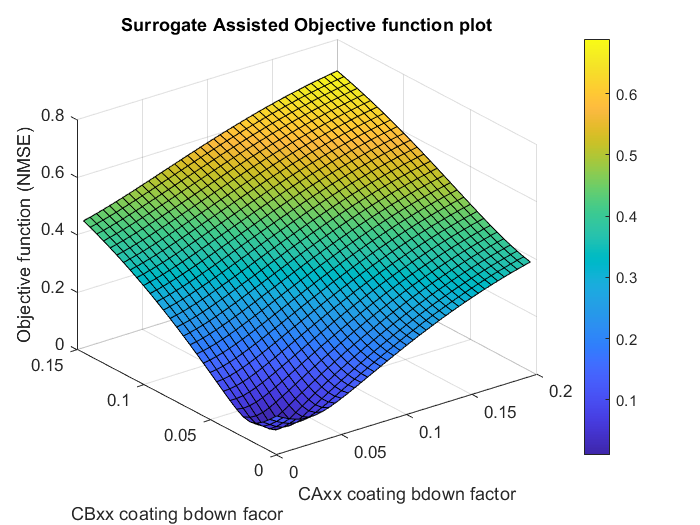

figure;

ax = gca;

[plot_data,fmin,  min_out_pos1] = plot_objective_with_surrogates(ax, DOE_range1, surrogates_0, calib_data_inc_error, 'nmsq', calib_data_type, [length(IDs{1}), length(IDs{2})],[1,0.5], [0.005,0.005]);

output_from_surrogate = output_from_surrogates(min_out_pos1, surrogates_0,[length(IDs{1}), length(IDs{2})]); 

xlabel('CAxx coating bdown factor');
ylabel('CBxx coating bdown facor');

min_out_pos1

min_out_pos1 =     0.0200    0.0200


testing_par_value = min_out_pos1;

solution_folder = '';
for i = 1:length(parameters)
    solution_folder =   strcat(solution_folder, parameters{i},'_', num2str(testing_par_value(i), '%.4f'));
    if i~=length(parameters)
        solution_folder = strcat(solution_folder, '_');
    end
end
solution_colection_dir = fullfile(root_folder,'Solution_results');

solution_dir = fullfile(solution_colection_dir, solution_folder);

if ~isfolder(solution_dir)
    solution_dict = py.BEASY_IN_OUT2.get_response_data_for_IDs_and_input_parameters(py.list(source_parameters), py.list(parameters), testing_par_value, simulation_seed_folder, solution_colection_dir,  py.list(response_data_type), py.list(IDs),  py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,1);
else

    solution_dict = py.BEASY_IN_OUT2.get_output_data_for_IDs_from_simulation_folder(solution_dir, files_name, py.list(response_data_type),  py.list(IDs), py.list(IDs_types));
    solution_data = convert_pydict2data(solution_dict,0);
end

%}


figure;

ax = gca;

%difference_in_bar_chart(ax,solution_data{1}(1:3:end,:), calib_data_inc_error{1}(1:3:end,:),{'simulation data from calibrated model','calibration data', 'difference'});
%difference_in_bar_chart(ax,solution_data{1}(1:3:end,:), output_from_surrogate{1}(1:3:end,:),{'simulation data from calibrated model','calibration data', 'difference'});
%difference_in_bar_chart(ax,test_data{4}(1:25:end,:), test_output_from_surrogate{4}(1:25:end,:),{'simulation output data','surrogate output data', 'difference'});
difference_in_bar_chart(ax,test_data{4}, test_output_from_surrogate{4},{'simulation output data','poly-fit model output data', 'difference'});

set(ax,'XAxisLocation','bottom');

%xlabel('Internal Points IDs');
xlabel('anode IDs');
ylabel('consumption rate (kg/yr)')
%ylabel('Z electric field (micro-V/m)');
%ylim([-1100 -950]);
%}

%solution_points = [0.02 0.02; 0.085 0.06; 0.145 0.105];
figure;
%scatter( previous_sample_points(:,1),  previous_sample_points(:,2), 'filled');

scatter( DOE_sample_points1(:,1),  DOE_sample_points1(:,2), 'filled');
hold on;
%scatter( DOE_sample_points20(:,1),  DOE_sample_points20(:,2), 'filled', 'g');
%scatter( DOE_sample_points20(1:4,1),  DOE_sample_points20(1:4,2), 'filled', 'g');
%scatter(  added_sample_Points(:,1),  added_sample_Points(:,2), 'filled', 'g');
scatter( testing_par_value(1), testing_par_value(2), 'filled', 'g');

%scatter(solution_points(:,1), solution_points(:,2), 'filled','c');
xlabel('CAxx coating bdown factor');
ylabel('CBxx coating bdown facor');

figure;

ax = gca;

response_plot_3d(ax, calib_data_inc_error, calib_data_inc_error, 1, 'voltage','Internal Points', files_name, calib_dir)
    
hold on;

%response_plot_3d(ax, calib_data_inc_error, calib_data_inc_error, 2, 'current density','Mesh Points', files_name, calib_dir, 'g')

function output_data = convert_pydict2data2(py_dict_data, extra_cell_provided)

output_data = cell(size(py_dict_data,2)-extra_cell_provided,1);

for i = 1:size(py_dict_data,2)-extra_cell_provided
    output_data{i} = convert_py_list_to_mat_arr(py.model_validation1.get_list_of_values(py_dict_data{i+extra_cell_provided}));
end
end


function de_normaised_data = reverse_normalization(normalised_data, value_ranges)

de_normaised_data = zeros(size(normalised_data));

for i = 1:size(normalised_data, 2)
    
    de_normaised_data(:,i) = value_ranges(i,1)+ diff(value_ranges(i,:))/2 * (normalised_data(:,i)-(-1));
    
end
end